# Sampling a univariate normal distribution via the ParaMonte library's ParaDRAM routine

**NOTE**

For a more comprehensive discussion of different aspects and attributes of  the sampler and how to run the simulation in parallel, see [the multivariate Normal distribution Jupyter Notebook example](https://nbviewer.jupyter.org/github/cdslaborg/paramontex/blob/master/Jupyter/Python/sampling_multivariate_normal_density_function_via_paradram.ipynb) in the same folder as this MATLAB live script file exists.

**NOTE**

 This ParaDRAM sampler example is **also available in Python language** as a Jupyter Notebook, on this page,  

[https://nbviewer.jupyter.org/github/cdslaborg/paramontex/blob/master/Jupyter/Python/sampling_univariate_gaussian_density_function_via_paradram.ipynb](https://nbviewer.jupyter.org/github/cdslaborg/paramontex/blob/master/Jupyter/Python/sampling_univariate_gaussian_density_function_via_paradram.ipynb)

This Jupyter Notebook, along with other Python Jupyter Notebooks, is located at,

[https://github.com/cdslaborg/paramontex/tree/master/jupyter/Python](https://github.com/cdslaborg/paramontex/tree/master/jupyter/Python)

First, we will clean up the MATLAB environment and make sure the path to the ParaMonte library is in MATLAB's path list.

clc;
clear all;
close all;
format compact; format long;

%%%%%%%%%%%% IMPORTANT %%%%%%%%%%%%%
% Set the path to the ParaMonte library:
% Change the following path to the ParaMonte library root directory, 
% otherwise, make sure the path to the ParaMonte library is already added
% to MATLAB's path list.

pmlibRootDir = './';
addpath(genpath(pmlibRootDir));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% change MATLAB's working directory to the folder containing this script
% if MATLAB Live Scripts did not create a temporary folder, we would not
% have all of these problems!

try
    setwd; % You can download this file from the same location where you downloaded this MATLAB live script on GitHub.
catch % alas, we will have to run the simulations in MATLAB Live Script's temporary folder
    filePath = mfilename('fullpath');
    [currentDir,fileName,fileExt] = fileparts(filePath); cd(currentDir);
    cd(fileparts(mfilename('fullpath'))); % Change working directory to source code directory.
end

Suppose we want to sample random points from a [standard univariate Gaussian function](https://en.wikipedia.org/wiki/Normal_distribution). The following MATLAB function `getLogFunc()` returns the natural logarithm of the Probability Density Function of the univariate standard Gaussian distribution.

NDIM = 1 % number of dimensions of the domain of the objective function

NDIM =      1

logSqrt2Pi = log(sqrt(2*pi));
getLogFunc = @(x) -0.5 * x^2 - logSqrt2Pi; % the objective function

**IMPORTANT**

Since the mathematical objective functions (e.g., probability density functions) can take extremely small or large values, we often work with their **natural logarithms** of the objective functions instead of the objective function itself. This is **the reason behind the naming convention used in the ParaMonte library** for the user's objective functions: **getLogFunc**, indicating that the **user must provide a function that returns the natural logarithm of the target objective function**.  

**IMPORTANT**

Note that in MATLAB all vectors and arrays are, by default, **column-major**, and so is the input value, **point**, to **getLogFunc**. This means that the size of **point** is **(ndim,1)**. Thus, **all other vectors **that interact with **point**, for example, the **mean **vector, **must be **also of **the same size as point**: **(ndim,1)**.

We will sample random points from this objective function by calling the **ParaDRAM** sampler (**Delayed-Rejection Adaptive Metropolis-Hastings Markov Chain Monte Carlo sampler**) of the ParaMonte library. The simplest scenario would be to run the simulation with the default specifications that are appropriately determined by the ParaDRAM  sampler. However, for further clarity of this particular example, we will  specify an output folder for the automatically-named output files of the simulation.

**NOTE**

**To run the sampler in parallel**, you will have to first save the MPI-enabled script as an external file. Visit the [ParaMonte library's documentation website](http://cdslab.org/paramonte/notes/run/matlab/) for more information.

We will first create an instance of the **paramonte** class and then, a ParaDRAM sampler instance from that,

pm = paramonte();
pmpd = pm.ParaDRAM();

% the forward-slash below indicates that the provided string should be treated 
% as the folder name and not as the prefix for the simulation output files.
pmpd.spec.outputFileName = "sampling_univariate_gaussian_density_function_via_paradram/";

% we will also request a much smaller number of uniquely-sampled points (5000)
% than the sampler's default value (100000).
pmpd.spec.chainSize = 5000;

% initialize the random seed to generate reproducible results
pmpd.spec.randomSeed = 31951;

% run the ParaDRAM sampler
pmpd.runSampler ( 1 ... This is the number of dimensions of the objective function
                , getLogFunc ... This is the objective function
                )

ParaDRAM - NOTE: Running the ParaDRAM sampler in serial mode...
ParaDRAM - NOTE: To run the ParaDRAM sampler in parallel mode visit: cdslab.org/pm


************************************************************************************************************************************
************************************************************************************************************************************
****                                                                                                                            ****
****                                                                                                                            ****
****                                                         ParaMonte                                                          ****
****                                                  Plain Powerful Parallel                                                   ****
****                                                 

This will print the realtime simulation progress information on your **MATLAB prompt window** (if you are on a Windows system) and on the **Bash terminal** from which you invoked the **matlab** command to open MATLAB. Once the simulation is finished,  the ParaDRAM routine generates a number of output files in the folder specified by the simulation specification variable `pmpd.spec.outputFileName`. Each of the output files contains information about certain aspects of the simulation. To understand the contents and utilities of these files, simply open them to look at their contents or visit this page:

[https://www.cdslab.org/paramonte/notes/usage/paradram/output/](https://www.cdslab.org/paramonte/notes/usage/paradram/output/)

Upon finishing the simulation, the sampler provides hints on how to postprocess the results. Now, we can read the generated output sample, contained in the file suffixed with `*_sample.txt`. 

pmpd.readSample()

ParaDRAM - WARNING: The ParaDRAM input simulation specification pmpd.spec.outputDelimiter is not set.
ParaDRAM - WARNING: This information is essential for successful reading of the requested sample file(s).
ParaDRAM - WARNING: Proceeding with the default assumption of comma-delimited sample file contents...

ParaDRAM - NOTE: 1 files detected matching the pattern: 
ParaDRAM - NOTE: "D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\sampling_univariate_gaussian_density_function_via_paradram\ParaDRAM_run_20200607_180837_732*"


ParaDRAM - NOTE: processing file: 
ParaDRAM - NOTE: D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\sampling_univariate_gaussian_density_function_via_paradram\ParaDRAM_run_20200607_180837_732_process_1_sample.txt
ParaDRAM - NOTE: reading file contents... 
ParaDRAM - NOTE: done in 1.342400 seconds.
ParaDRAM - NOTE: computing the sample correlation matrix...
ParaDRAM - NOTE: creating the heatmap plot object from scratch...
ParaDRAM - NOTE: do

To quickly visualize the generated sample as a histogram, try,

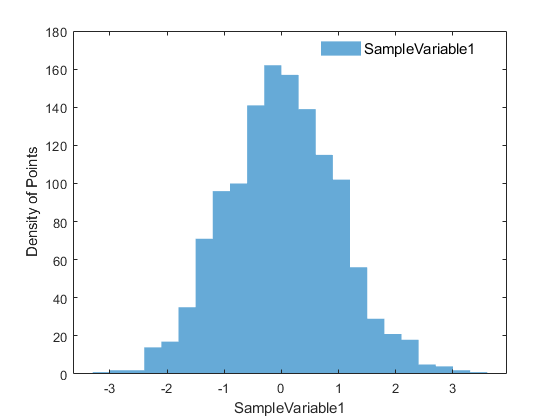

pmpd.sampleList{1}.plot.histogram.plot();

If the variable names are specified for the sampler before running  the simulations, the sampler will automatically assign names to each  variable. To change the x-label, for example, you can try,

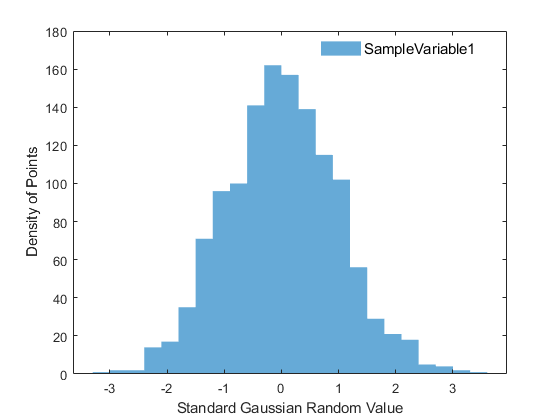

pmpd.sampleList{1}.plot.histogram.plot();
xlabel("Standard Gaussian Random Value");

To make a trace-plot of the sample, try, 

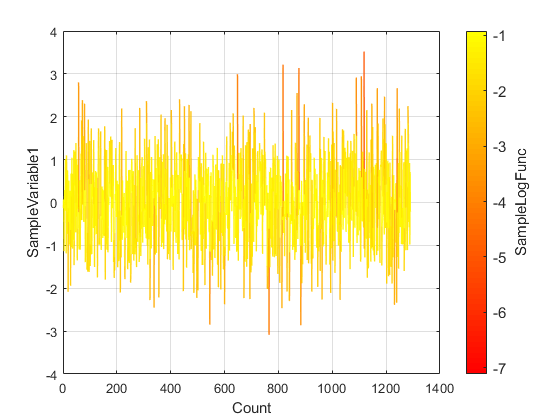

pmpd.sampleList{1}.plot.line.plot();

Make the trace-plot of the sample on the logarithmic scale, try, 

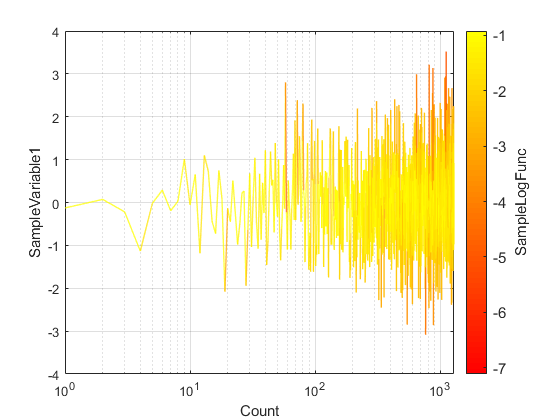

pmpd.sampleList{1}.plot.line.plot();
set(gca,'xscale','log','yscale','linear');

There are many other properties of the plot that can be set or modified via the attributes of the `pmpd.sampleList{1}.plot.line` object. To see them all, get help about the object,

pmpd.sampleList{1}.plot.line.helpme()

To make a scatter plot of the sampled points, try,

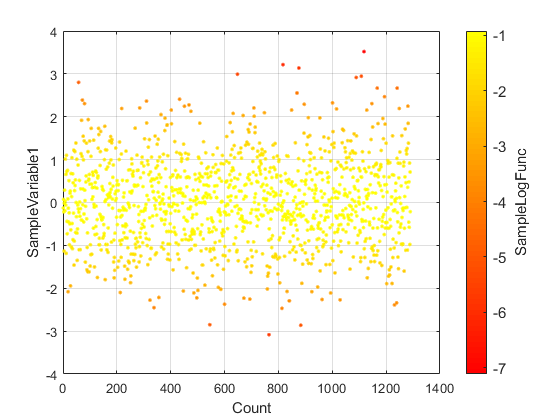

pmpd.sampleList{1}.plot.scatter.scatter_kws.size = 50; % make the dots slightly larger than the default
pmpd.sampleList{1}.plot.scatter.plot()

Setting or modifying the properties of the scatter plot is highly similar to the procedures used for the line plot. To turn the varying-color off, try,

pmpd.sampleList{1}.plot.reset("scatter"); % reset the scatter plot settings to the default.

ParaDRAM - NOTE: resetting the properties of the scatter plot...


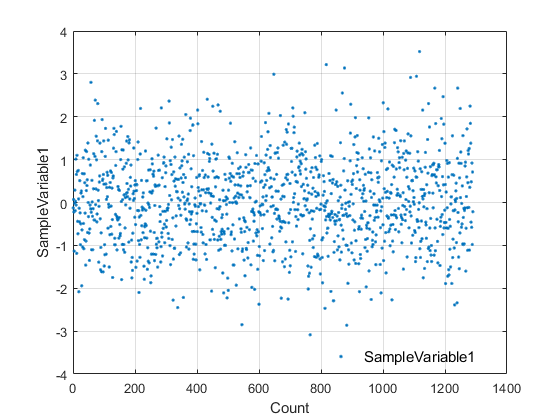

pmpd.sampleList{1}.plot.scatter.scatter_kws.cdata = []; % this activates the use of MATLAB's default colors 
pmpd.sampleList{1}.plot.scatter.scatter_kws.size = 30; % make the dots slightly larger
pmpd.sampleList{1}.plot.scatter.plot()

Let's make some (2D or 3D) kernel density estimates of the sampled points. To increase the quality of the kernel density estimates, we will use the raw Markov chain data (in compact format),

pmpd.readChain()

ParaDRAM - WARNING: The ParaDRAM input simulation specification pmpd.spec.outputDelimiter is not set.
ParaDRAM - WARNING: This information is essential for successful reading of the requested chain file(s).
ParaDRAM - WARNING: Proceeding with the default assumption of comma-delimited chain file contents...
ParaDRAM - NOTE: 1 files detected matching the pattern: 
ParaDRAM - NOTE: "D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\sampling_univariate_gaussian_density_function_via_paradram\ParaDRAM_run_20200607_180837_732*"

ParaDRAM - NOTE: processing file: 
ParaDRAM - NOTE: D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\sampling_univariate_gaussian_density_function_via_paradram\ParaDRAM_run_20200607_180837_732_process_1_chain.txt
ParaDRAM - NOTE: reading file contents... 
ParaDRAM - NOTE: done in 0.138030 seconds.
ParaDRAM - NOTE: computing the sample correlation matrix...
ParaDRAM - NOTE: creating the heatmap plot object from scratch...
ParaDRAM - NOTE: done in

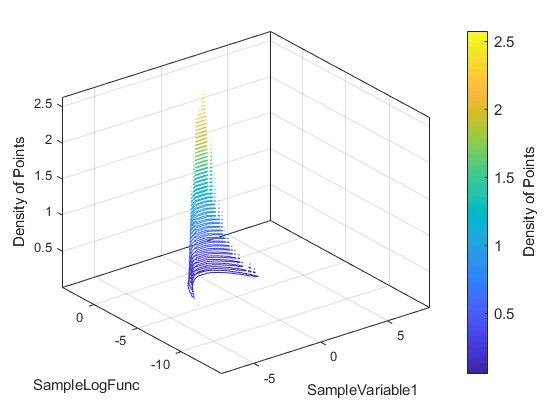

pmpd.chainList{1}.plot.contour3.gridSize = 128; % the default is 512
pmpd.chainList{1}.plot.contour3.plot();

Since there is no more than one sampled variable here, the kernel density plot displays SampleLogFunc vs. `SampleVariable1`.

To visualize the autocorrelation of the raw MCMC chain, try,

pmpd.readMarkovChain() % first read the chain

ParaDRAM - WARNING: The ParaDRAM input simulation specification pmpd.spec.outputDelimiter is not set.
ParaDRAM - WARNING: This information is essential for successful reading of the requested chain file(s).
ParaDRAM - WARNING: Proceeding with the default assumption of comma-delimited chain file contents...

ParaDRAM - NOTE: 1 files detected matching the pattern: 
ParaDRAM - NOTE: "D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\sampling_univariate_gaussian_density_function_via_paradram\ParaDRAM_run_20200607_180837_732*"


ParaDRAM - NOTE: processing file: 
ParaDRAM - NOTE: D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\sampling_univariate_gaussian_density_function_via_paradram\ParaDRAM_run_20200607_180837_732_process_1_chain.txt
ParaDRAM - NOTE: reading file contents... 
ParaDRAM - NOTE: done in 0.139350 seconds.
ParaDRAM - NOTE: computing the sample correlation matrix...
ParaDRAM - NOTE: creating the heatmap plot object from scratch...
ParaDRAM - NOTE: done 

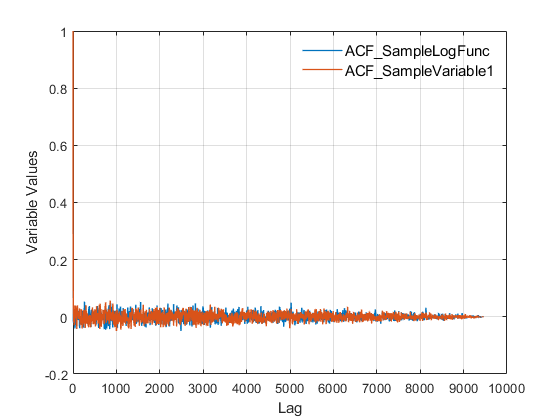

pmpd.markovChainList{1}.stats.autocorr.plot.line.plot();

For better visualization, let's make the axis logarithmic,

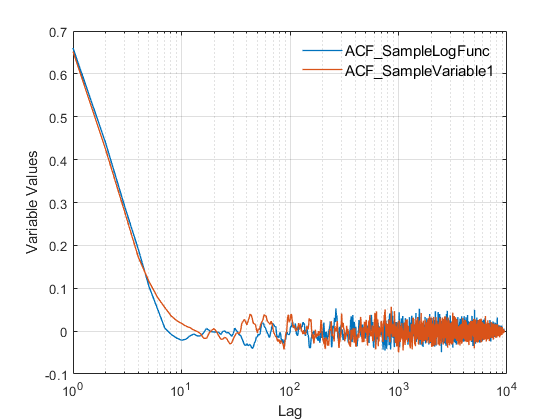

pmpd.markovChainList{1}.stats.autocorr.plot.line.plot();
set(gca,'xscale','log','yscale','linear');

Now, for comparison, let's plot the autocorrelation of the final sample, which heavily and agressively refined by the ParaDRAM sampler,

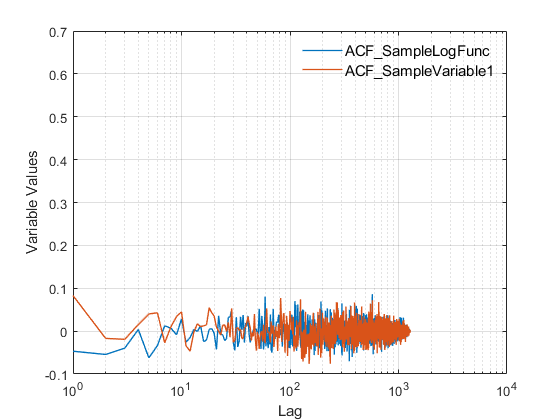

pmpd.sampleList{1}.stats.autocorr.plot.line.plot();
ylim(pmpd.markovChainList{1}.stats.autocorr.plot.line.currentFig.gca.YLim) % for better comparison, set the Y-axis range to that of the Markov chain plot
xlim(pmpd.markovChainList{1}.stats.autocorr.plot.line.currentFig.gca.XLim) % for better comparison, set the X-axis range to that of the Markov chain plot
set(gca,'xscale','log','yscale','linear');

The above AutoCorrelation plot for the refined sample is reassuring since the sampled points do not appear to be correlated with each other at all. This is because the ParaDRAM routine, by default, applies as many rounds of refinements and decorrelating of the Markov chain as necessary to remove any residual correlations from the final output random sample.

By contrast, unlike the refined sample, the Markov chain is significantly correlated  with itself along each dimension. The large amount of autocorrelation  seen for `SampleLogFunc` is because of the fact that we  started the MCMC sampling from a very bad low-probability location,  which is also visible the grid plots in the above.

## Final Remarks

**=================**

**There are many more functionalities and features of the  ParaMonte library that were neither explored nor mentioned in this  example Jupyter notebook. You can explore them by checking the existing  components of each attribute of the ParaDRAM sampler class and by  visiting the **[**ParaMonte library's documentation website**](http://cdslab.org/paramonte/).